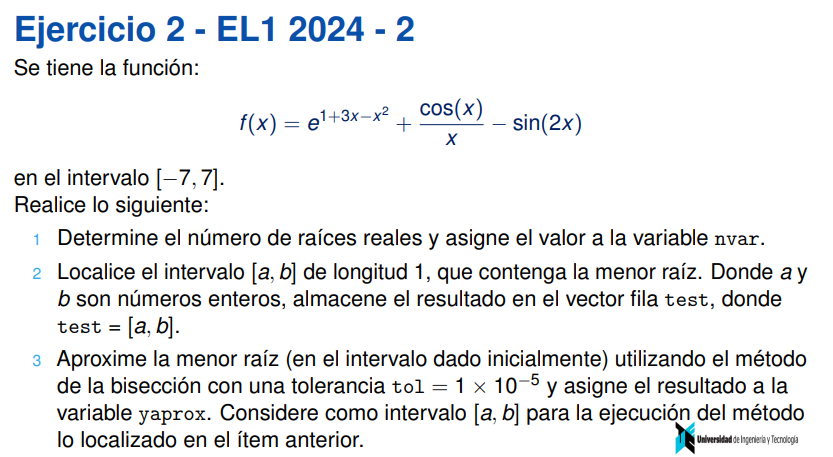

clear
clc

f = @(x) exp(1+3*x-x.^2) + cos(x)./x - sin(2*x);

% Intervalos donde se buscarán cambios de signo
A = [-7 -6 -5 -4 -3 -2 -1  0.0001 1 2 3 4 5 6];
B = [-6 -5 -4 -3 -2 -1 -0.0001 1      2 3 4 5 6 7];

nvar = 0;
intervalos = [];

for k = 1:length(A)

    if f(A(k))*f(B(k)) < 0

        nvar = nvar + 1;
        intervalos(nvar,:) = [A(k) B(k)];

    end

end

nvar

nvar = 8

intervalos

intervalos =    -7.0000   -6.0000
   -5.0000   -4.0000
   -3.0000   -2.0000
   -2.0000   -1.0000
   -1.0000   -0.0001
    3.0000    4.0000
    4.0000    5.0000
    6.0000    7.0000


Intervalo de longitud

a = -7;
b = -6;

test = [a b]

test =     -7    -6


Aproximar la raíz por bisección con Tol=10^-5

tol = 1e-5;

a = test(1);
b = test(2);

iter = 0;

while (b-a)/2 > tol

    c = (a+b)/2;

    if f(c) == 0
        break
    end

    if f(a)*f(c) < 0
        b = c;
    else
        a = c;
    end

    iter = iter + 1;

end

yaprox = (a+b)/2;

yaprox

yaprox = -6.3619

iter

iter = 16

Completo

clear
clc

f = @(x) exp(1+3*x-x.^2) + cos(x)./x - sin(2*x);

%% 1. Numero de raices

A = [-7 -6 -5 -4 -3 -2 -1 0.0001 1 2 3 4 5 6];
B = [-6 -5 -4 -3 -2 -1 -0.0001 1 2 3 4 5 6 7];

nvar = 0;
intervalos = [];

for k = 1:length(A)

    if f(A(k))*f(B(k)) < 0
        nvar = nvar + 1;
        intervalos(nvar,:) = [A(k) B(k)];
    end

end

nvar

nvar = 8

intervalos

intervalos =    -7.0000   -6.0000
   -5.0000   -4.0000
   -3.0000   -2.0000
   -2.0000   -1.0000
   -1.0000   -0.0001
    3.0000    4.0000
    4.0000    5.0000
    6.0000    7.0000



%% 2. Intervalo de la menor raiz

a = -7;
b = -6;

test = [a b]

test =     -7    -6



%% 3. Metodo de biseccion

tol = 1e-5;
iter = 0;

while (b-a)/2 > tol

    c = (a+b)/2;

    if f(c) == 0
        break
    end

    if f(a)*f(c) < 0
        b = c;
    else
        a = c;
    end

    iter = iter + 1;

end

yaprox = (a+b)/2

yaprox = -6.3619


iter

iter = 16